# 4 OCR system construction and system testing

## Summary

Note* - Error rate = 1 - hitrate

The hitrate for version 1:

Short1: 62% 

Short2: 72%

Home1: 5.6%

Home2: 5.9%

Home3: 6.1%

The hitrate for version 2:

Short1: 72%

Short2: 74%

Home1: 52%

Home2:  56.6%

Home3: 57.9%

Based on the result for both version, version 2 performed 9 times better on correctly classifying characters. The reason version 2 did better because the feature extraction is not relying on the input images to have the same size when the characters segmented. Version 1 heavily relied on same size image and character size, thickness inorder to have a consistent and accurate result.

Changed the feature extraction for version 2. After getting the extracted image, it zooms in on the character, resizes all image to be around 50pixel tall. That way, there is some consistency with the dimension of the image. Then I feed it into the feature extraction from version 1 and added a few more features such as the orientation, EulerNumber and such from region props.

I have a hard time push improving the hitrate the homes' data set. I tried to improve on the segmentation, but then it did not perform well for the shorts' dataset. I google scholar papers and techniques research had used to improve OCR, but a lot of them uses a neural network. I tried but did not succeed in the time being. I will have to work it out after this course.

## Version 1 of OCR Results for 5 datasets

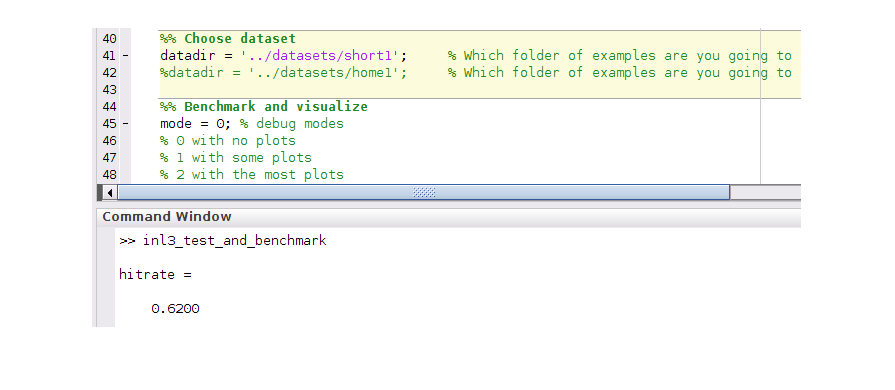


[im, s] = imread('q4t1s1','png');
imshow(im);

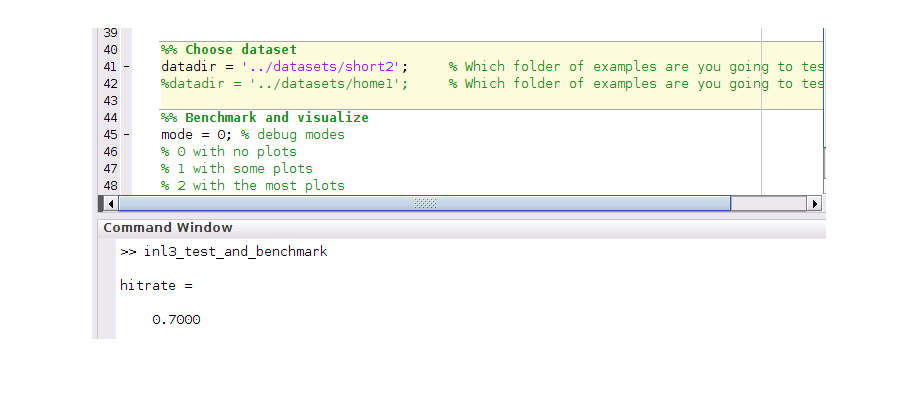


[im, s] = imread('q4t1s2','png');
imshow(im);

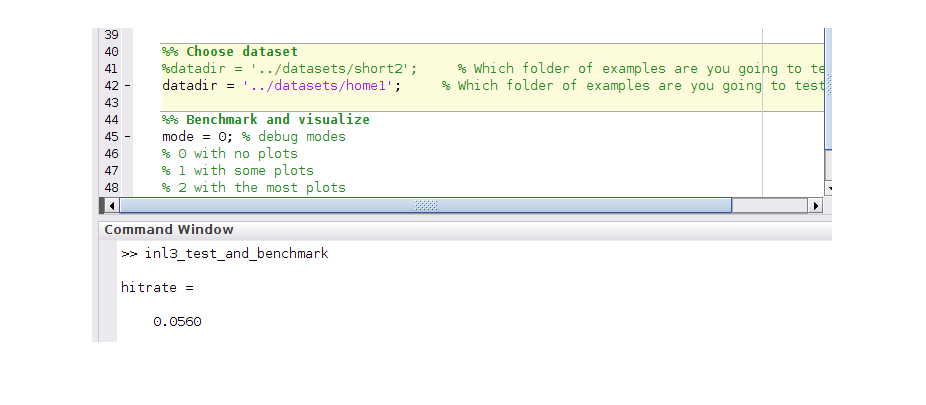


[im, s] = imread('q4t1h1','png');
imshow(im);

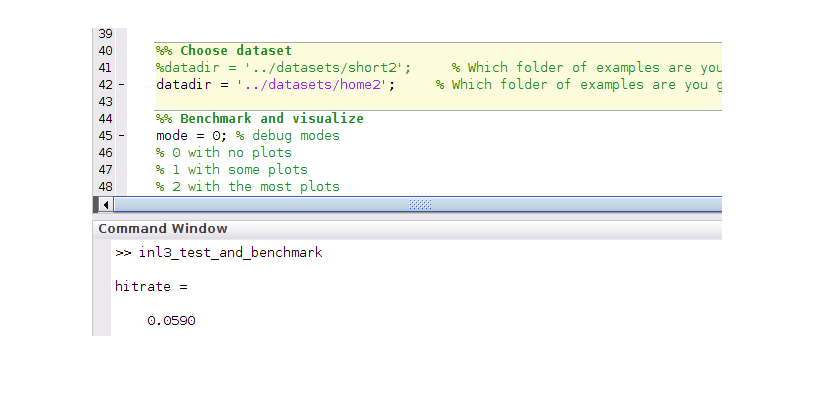


[im, s] = imread('q4t1h2','png');
imshow(im);

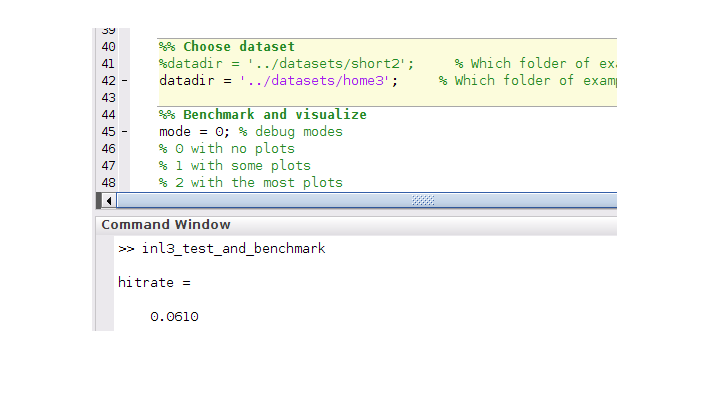


[im, s] = imread('q4t1h3','png');
imshow(im);

## Version 2 of OCR Results for 5 datasets

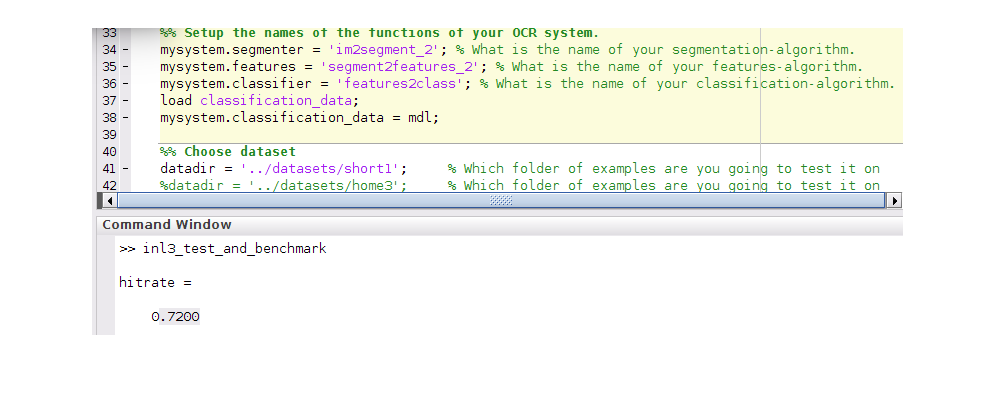

[im, s] = imread('q4t2s1','png');
imshow(im);

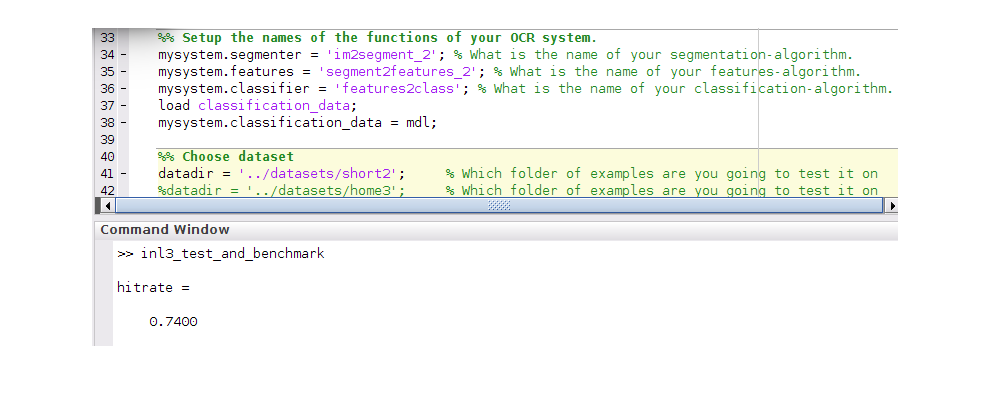


[im, s] = imread('q4t2s2','png');
imshow(im);

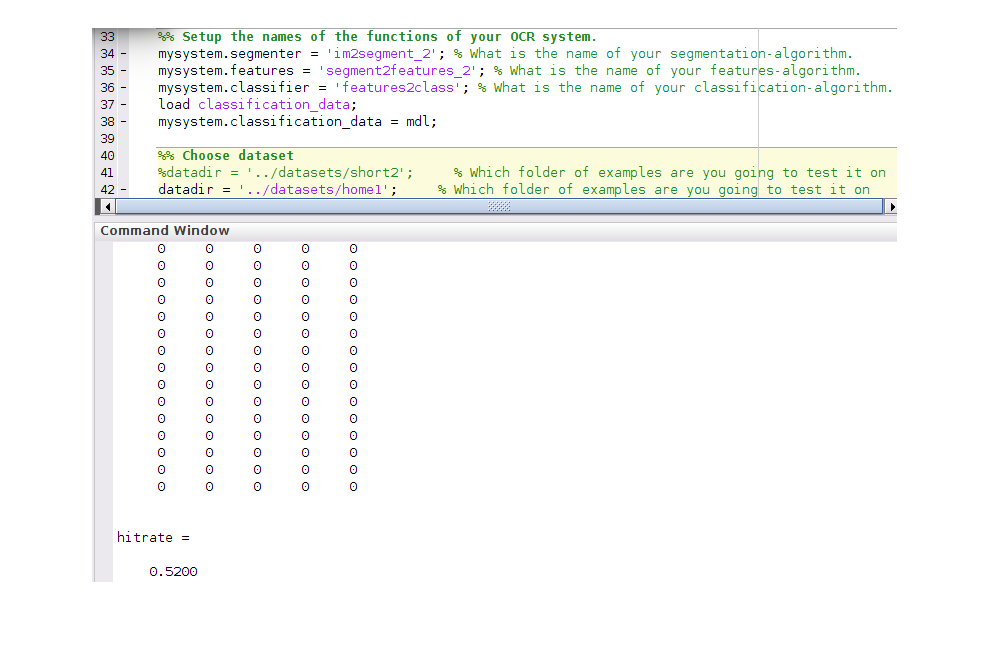


[im, s] = imread('q4t2h1','png');
imshow(im);

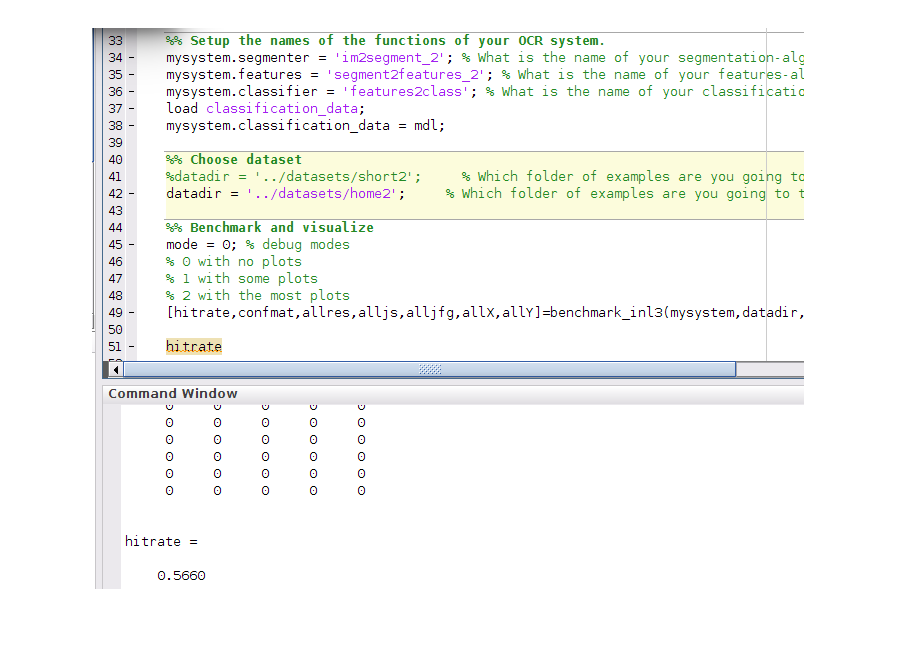


[im, s] = imread('q4t2h2','png');
imshow(im);

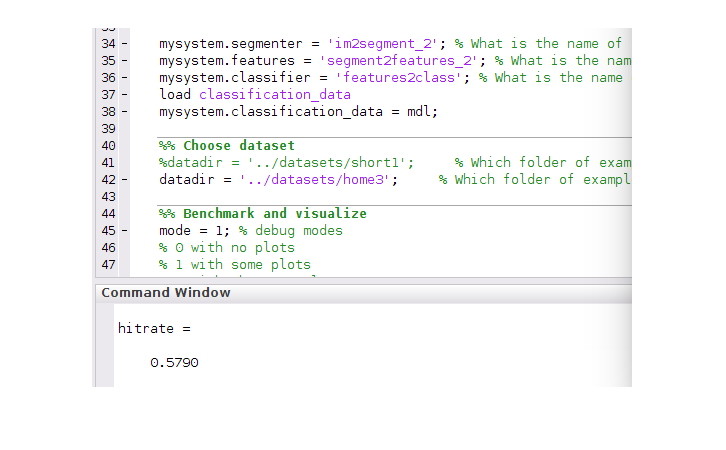


[im, s] = imread('q4t2h3','png');
imshow(im);

## Code

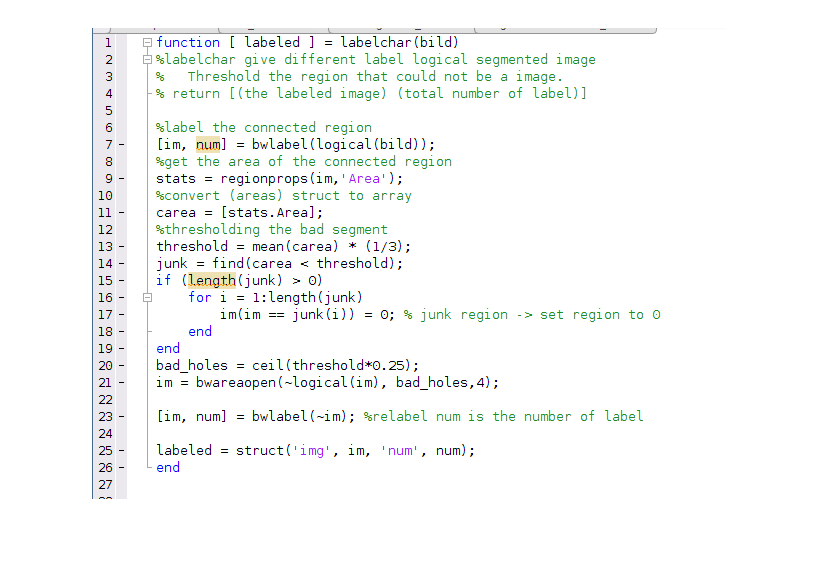


[im, s] = imread('q4c1','png');
imshow(im);

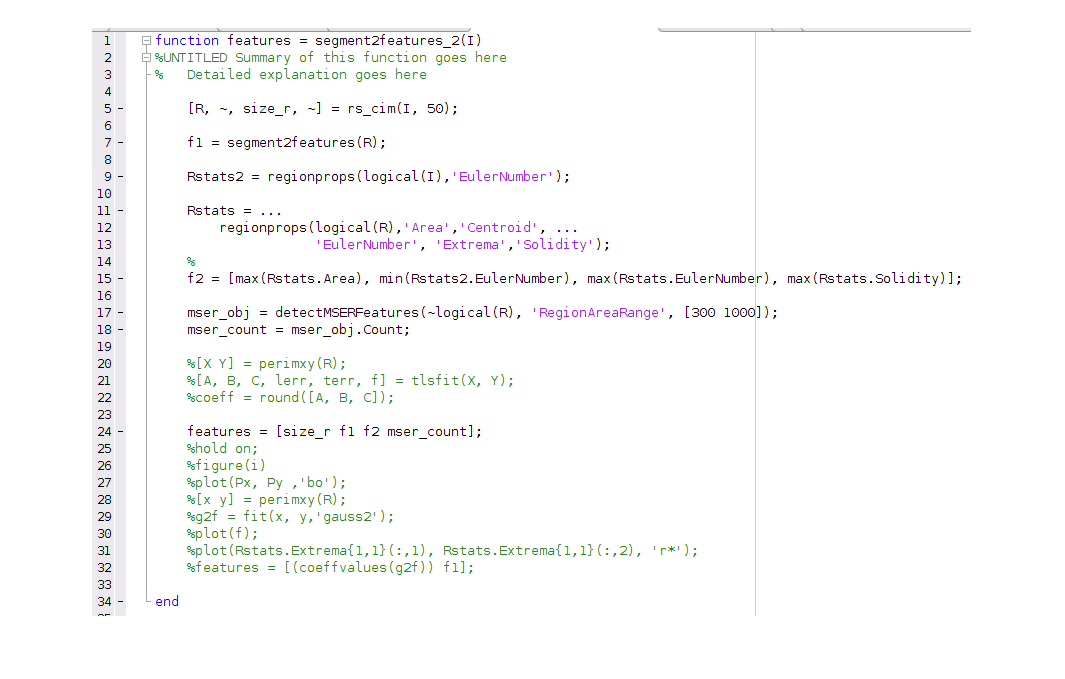


[im, s] = imread('q4c2','png');
imshow(im);

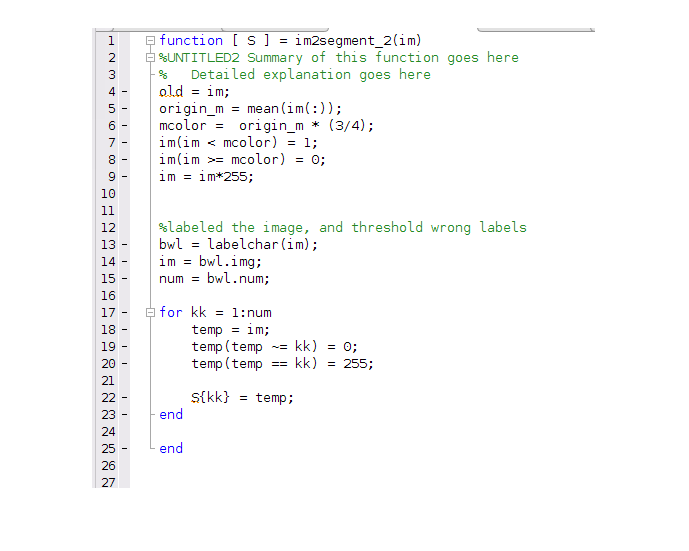


[im, s] = imread('q4c3','png');
imshow(im);

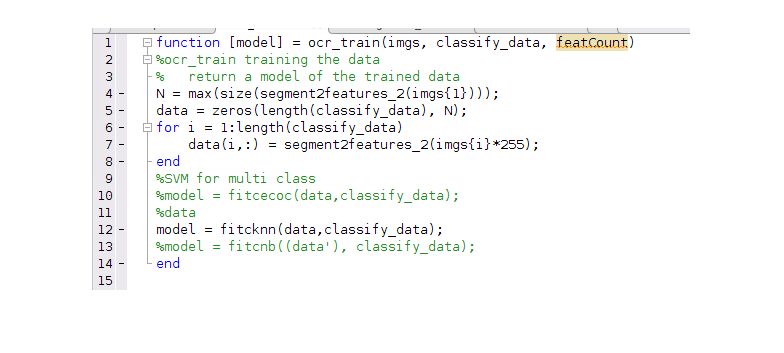


[im, s] = imread('q4c4','png');
imshow(im);